mu = 1; % Population parameter
n = 1e3; % Sample size
ns = 1e4; % Number of samples

rng('default')  % For reproducibility
samples = exprnd(mu,n,ns); % Population samples
means = mean(samples); % Sample means
[phat,pci] = mle(means)

phat =     1.0000    0.0315


pci =     0.9994    0.0311
    1.0006    0.0319


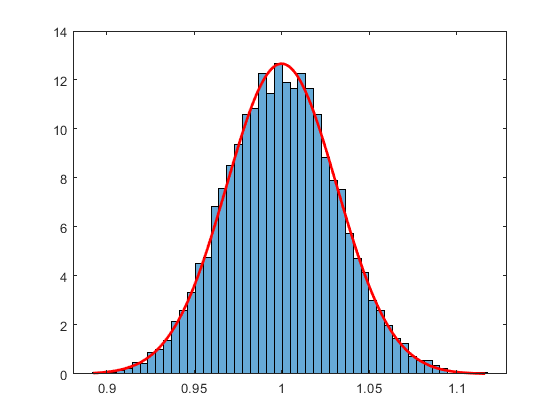

numbins = 50;
histogram(means,numbins,'Normalization','pdf')
hold on
x = min(means):0.001:max(means);
y = normpdf(x,phat(1),phat(2));
plot(x,y,'r','LineWidth',2)